# Versuch 1 - Modellierung und Simulation eines Doppelpendel-Systems Praktikum MATLAB®/Simulink® II

## Teilnehmer

#### Teilnehmer 1

Name, Vorname: Brugnera Silva, Alessandro

Matrikelnummer: 2898524

#### Teilnehmer 2

Name, Vorname: Gouveia Freitas, Caio Victor

Matrikelnummer:  2328654

## Aufgaben

Die folgenden Aufgaben sind teilweise während des Versuchs zu lösen und am nächsten Versuchsnachmittag oder spätestens eine Woche später mit dem Protokoll den Betreuern abzugeben. Die Aufgaben, die während des Versuchs zu lösen sind, sind handschriftlich in die umrandeten Felder einzutragen.

### Aufgabe 1

Legen Sie die Parameter des Pendels und ihre Zahlenwerte in einem Skript (initModell.m) ab, so dass diese geändert werden können, ohne die Simulink-Modelle und Funktionen anpassen zu müssen.

edit initModell.m

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

% Kein Code erforderlich!

### Aufgabe 2

Vervollständigen Sie das das unten stehende Skript an den entsprechenden Stellen, um das Modell symbolisch herzuleiten. 

*Hinweise*: Sie können stattdessen auch ihre eigene Modellierungsmethoden verwenden. Speichern Sie ihre Systemgleichung jedoch wie angegeben in der Struktrur *Sol.*

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

%% Variablen

% Parameter
syms Rp1 Rp2 g m1 m2 l1 l2 J1 J2 t positive;

% Koordinaten
syms ddphi1 ddphi2 dphi1 dphi2 phi1 phi2 real;

% Kräfte
syms M real;


%% Zu ersetzende Größen

% Reibungen
MR1 = Rp1*dphi1;
MR2 = Rp2*(dphi2-dphi1);

% Trägheitsmoment duenner Stab
J1 = m1*(l1/2)^2/12;
J2 = m2*(l2/2)^2/12;

% Koordinaten des ersten Pendels
x1   = l1/2*sin(phi1); %calculated
dx1  = l1/2*cos(phi1)*dphi1; %derivate did by hand

% y goes up, so pendulum is down
y1   = -l1/2*cos(phi1);
dy1  = l1/2*sin(phi1)*dphi1;

% reference from 1 but L is not divided by 2, abolute reference
% Koordinaten des zweiten Pendels
x2   = l1*sin(phi1) + l2/2*sin(phi2);
dx2  = l1*cos(phi1)*dphi1 + l2/2*cos(phi2)*dphi2;

y2   = -l1*cos(phi1) + -l2/2*cos(phi2);
dy2  = l1*sin(phi1)*dphi1 + l2/2*sin(phi2)*dphi2;

%% Mechanik
% kinetische Energie des ersten Pendels
T1 = J1/2*dphi1^2 + m1/2*(dx1^2+dy1^2); 
% kinetische Energie des zweiten Pendels
T2 = J2/2*dphi2^2 + m2/2*(dx2^2+dy2^2);
% potentielle Energie des ersten Pendels
U1 = m2*g*y1;
% potentielle Energie des zweiten Pendels
U2 = m2*g*y2;

Qphi1   = M-MR1+MR2;
Qphi2   = -MR2;

L = T1+T2-U1-U2;

%% Herleitung der Ableitung nach generalisierter Koordinate
% 
% dL/dphi1
L_phi1 = jacobian(L,phi1);

% dL/ddphi1
L_dphi1 = jacobian(L,dphi1);

% dL/dphi2
L_phi2 = jacobian(L,phi2);

% dL/ddphi2
L_dphi2 = jacobian(L,dphi2);

% d(L_dxs)/dt und d(L_dphi)/dt

% Variablen ohne t durch Variablen mit t ersetzen
L_dphi1_t = subs(L_dphi1,{phi1,dphi1,phi2,dphi2}, ...
    str2sym({'phi1(t)','dphi1(t)','phi2(t)','dphi2(t)'}));
L_dphi2_t = subs(L_dphi2,{phi1,dphi1,phi2,dphi2}, ...
    str2sym({'phi1(t)','dphi1(t)','phi2(t)','dphi2(t)'}));

%Berechnung der Zeitableitung
dL_dphi1_t = diff(L_dphi1_t,t);
dL_dphi2_t = diff(L_dphi2_t,t);

% Variablen mit t
Var_t = str2sym({'phi1(t)','dphi1(t)','diff(phi1(t),t)','diff(dphi1(t),t)',...
    'phi2(t)','dphi2(t)','diff(phi2(t),t)','diff(dphi2(t),t)'});

% Variablen ohne t
Var_ot = {phi1,dphi1,dphi1,ddphi1,phi2,dphi2,dphi2,ddphi2};

% Variablen mit t durch Variablen ohne t wieder ersetzen
dL_dphi1_t = subs(dL_dphi1_t,Var_t,Var_ot);
dL_dphi2_t = subs(dL_dphi2_t,Var_t,Var_ot);

%% Berechnung der LAGRANGEschen Gleichungen

Sol = solve([dL_dphi1_t - L_phi1 == Qphi1,dL_dphi2_t - L_phi2 == Qphi2],[ddphi1,ddphi2])

Sol = struct with fields:
    ddphi1: -(24*(2*Rp1*dphi1*l2 - 24*M*l2*cos(phi2)^2 - 24*M*l2*sin(phi2)^2 - 2*M*l2 + 2*Rp2*dphi1*l2 - 2*Rp2*dphi2*l2 + 24*Rp1*dphi1*l2*cos(phi2)^2 + 24*Rp2*dphi1*l2*cos(phi2)^2 - 24*Rp2*dphi2*l2*cos(phi2)^2 + 24*Rp1*dphi1*l2*sin(phi2)^2 + 24*Rp2*dp…
    ddphi2: -(24*(2*Rp2*dphi2*l1*m1 - 2*Rp2*dphi1*l1*m1 - 24*Rp2*dphi1*l1*m1*cos(phi1)^2 - 96*Rp2*dphi1*l1*m2*cos(phi1)^2 + 24*Rp2*dphi2*l1*m1*cos(phi1)^2 + 96*Rp2*dphi2*l1*m2*cos(phi1)^2 + 48*M*l2*m2*cos(phi1)*cos(phi2) - 24*Rp2*dphi1*l1*m1*sin(phi1)…


Sol.ddphi1 = simplify(Sol.ddphi1);
Sol.ddphi2 = simplify(Sol.ddphi2);

### Einführung nichtlineare Modell

Das nichtlineare Modell soll jeweils mit Hilfe von

- Fcn-Blocks

- MATLAB-Function-Block sowie

- S-Function

realisiert werden. Implementieren Sie mit der in Aufgabe 2 ermittelten Gleichung die gegebenen Modelle.

*Hinweis: *Die gezeigten Abbildungen sind Beispiele die aus Subsystemen entnommen wurden. Im Verlauf des Versuchen müssen die Modelle angeregt werden. Daher sind an den Input-Ports jeweils geeignete Blöcke vorzusehen. 

### Aufgabe 3

**Fcn Blocks**

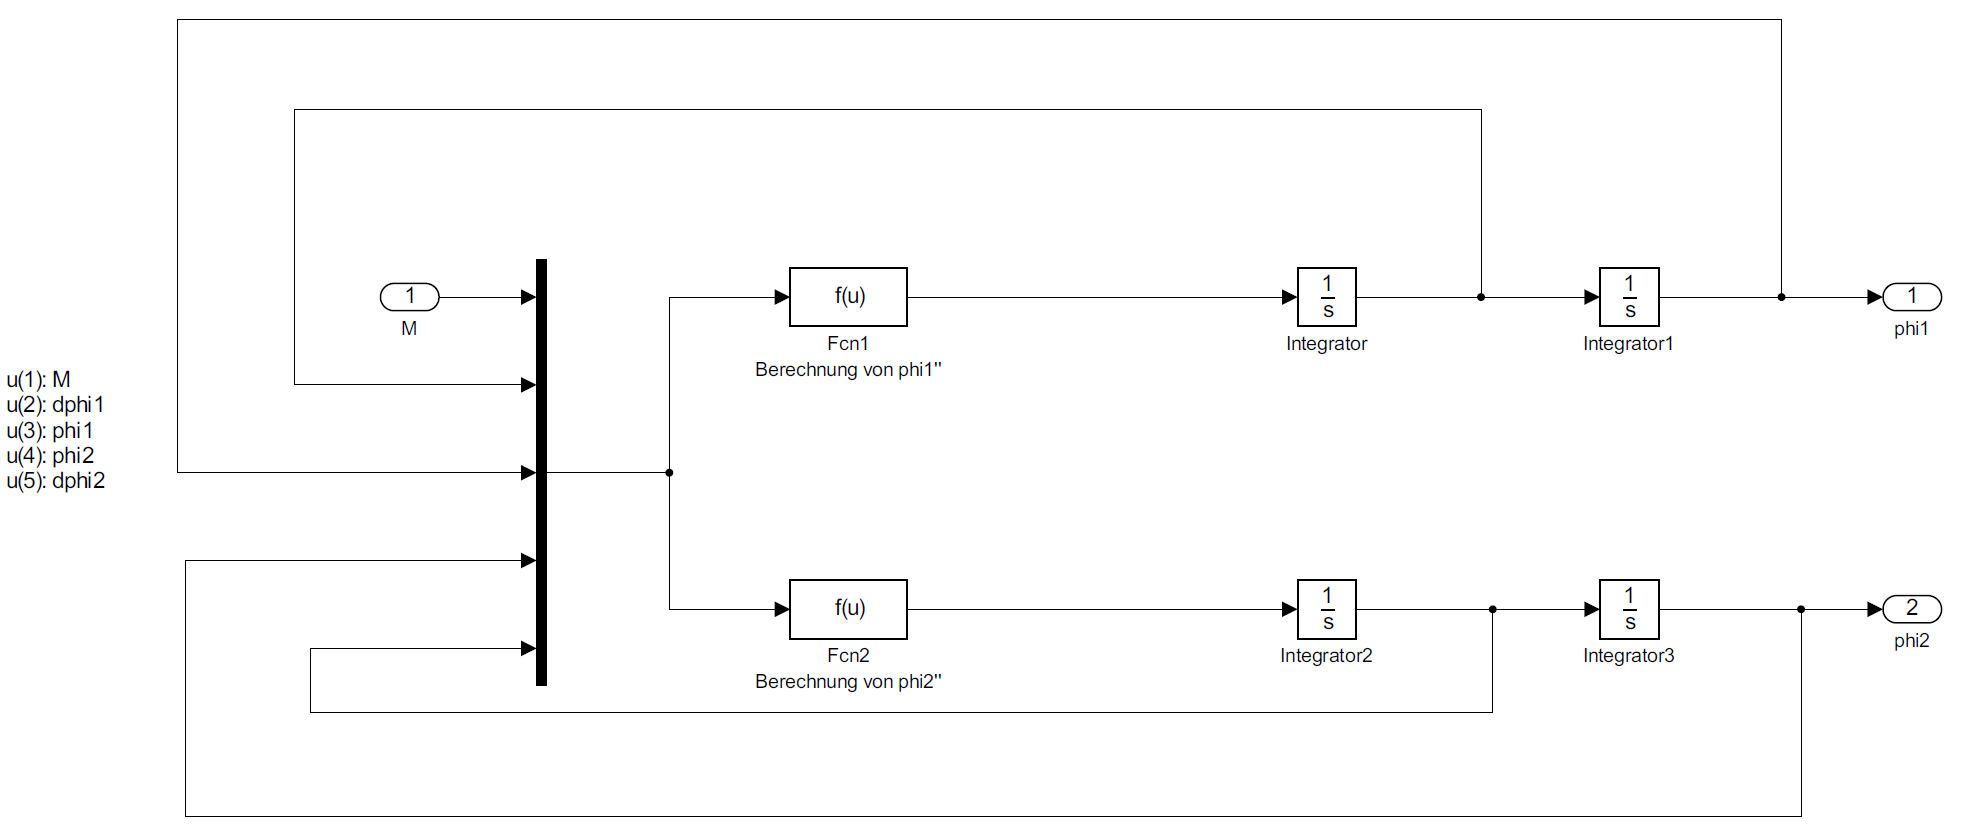

open_system('Modelle.slx')

Geben Sie die Gleichungen in den Blöcken Fcn1 und Fcn2 an. Die Ergebnisse sind als Strings im Livescript anzugeben. Des Weiteren nutzen Sie zur besseren Lesbarkeit den "..." Operator sobald die Ausdrücke den Rand des Fenster erreichen.

*Hinweis*: Zur einfacheren Ermittlung der einzufügenden Gleichung nutzen Sie die Funktion *strrep. *

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

Inhalt Fcn1

ddphi1Str = [""...
            ""];

Inhalt Fcn2

ddphi2str = [""...
            ""];

### Aufgabe 4

**MATLAB-Function-Block**

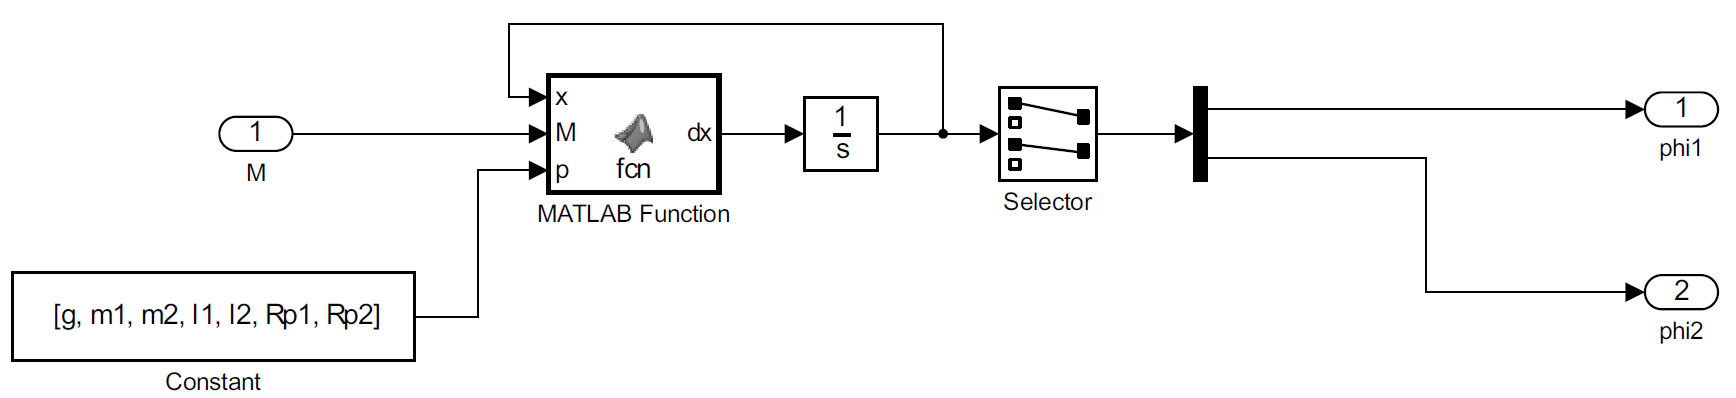

open_system('Modelle.slx')

Geben Sie die Funktion im MATLAB Function block **am Ende des Dokuments** in den dafür vorgesehenen Bereich an.

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

% Geben Sie die Funktion im MATLAB Function block am Ende des Dokuments 
% in den dafür vorgesehenen Bereich an

### Aufgabe 5

**s-Function**

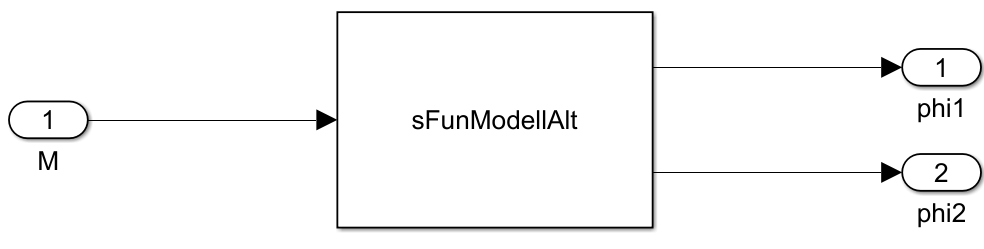

open_system('Modelle.slx')
edit sFunModell.m

#### Ihre Antwort:

Keine Antwort notwendig!

**Code und Plots zu Ihrer Antwort:**

% Kein Code erforderlich!

### Einführung Analyse

Verwenden Sie für die nachfolgenden Simulationen den ode45 (Dormand-Prince)-Solver und eine geeignete maximale Schrittweite (auf die MATLAB-Ausgabe während der Simulation achten). Verringern Sie die maximale Schrittweite, wenn die Graphen sehr kantig wirken. Zum Vergleich wird im Folgenden eine Simulation bei der Anfangsbedingung $x_0^{\top \;} =\left\lbrack \begin{array}{cccc}
\frac{\;\pi \;}{1,01} & 0 & \frac{\;\pi \;}{1,01} & 0
\end{array}\right\rbrack$ ohne Anregung ($M=0$) gezeigt.

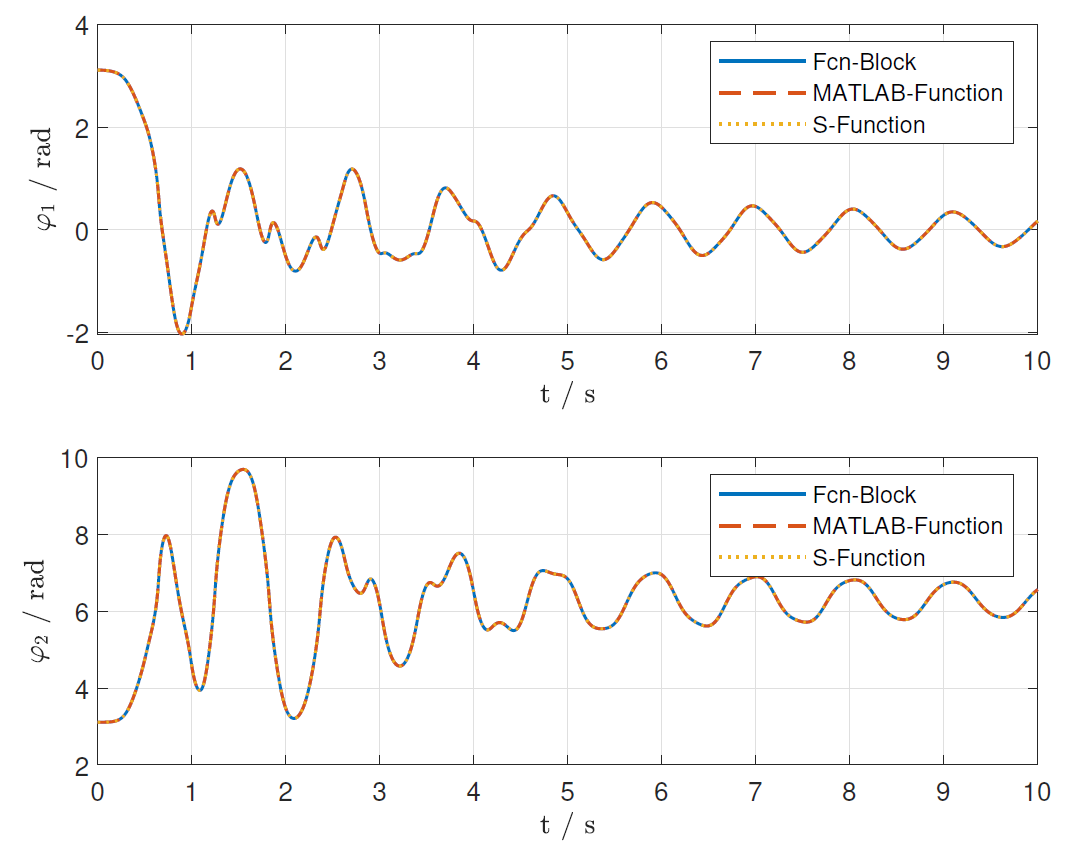

### Aufgabe 6

Untersuchen Sie das Verhalten bzw. die Reaktion der erstellten Modelle anhand der Auswertung der Signale $\varphi {\;}_1 \left(t\right)$ und $\varphi {\;}_2 \left(t\right)$ auf eine sinusförmige Anregung mit $M\left(t\right)=0,1\cdot \;\sin \left(\omega \;t\right)$mit $\omega =1\;\frac{\textrm{rad}}{s\;}$ für die Zeitspanne $t=0\;s$ bis $t=20\;s$ .

- Sind die Simulationsergebnisse aller drei nichtlinearen Modelle identisch? 

- Fertigen Sie dazu folgenden Plot mit Hilfe von subplot und linkaxes an: Stellen Sie im ersten Subplot die anregende Kraft $M\left(t\right)$, im zweiten die ersten Winkel $\varphi {\;}_1 \left(t\right)$ und im dritten die zweiten Winkel $\varphi {\;}_2 \left(t\right)$ dar. Vergessen Sie nicht die sinnvolle Achsenskalierung, die Achsenbeschriftung und die Verwendung unterschiedlicher Strichtypen!* (Für die Erstellung der Plots beachten Sie bitte den Abschnitt Physikalische Modellbildung *$\to$* Simulation *$\to$* Darstellung der Ergebnisse im Skript von Versuch 1. Die Nichtbeachtung der Richtlinien führt zu Punktabzug!)*

#### Ihre Antwort:

**Code und Plots zu Ihrer Antwort:**

### Aufgabe 7

Ist das Verhalten des Doppelpendels, welches Sie in Aufgabe 6 ermittelt habe, plausibel? Plotten Sie die Simulationsergebnisse für die ersten zwei Sekunden. Beschreiben Sie dazu die erwartete und die simulierte Reaktion des Modells für die ersten zwei Sekunden der Simulation. (Zu beachten sind $M\left(t\right)$, $\varphi {\;}_1 \left(t\right)$ und $\varphi_2 \left(t\right)$.)

#### Ihre Antwort:

**Code und Plots zu Ihrer Antwort:**

# Wichtige Anmerkung

**Strukturieren Sie ihren Code so, dass jede Sektion für sich ausführbar ist, und keine vorhergehenden Funktionen notwendig sind!** Muss beispielsweise ein Modell in mehreren aufgaben geladen werden, so laden Sie es in jedem Abschnitt erneut, insoweit nichts anderes angegeben ist.

Der Versuchsbericht in Form **dieses** Live Scriptes (einer pro Gruppe) ist anhand der oben aufgeführten Fragen anzufertigen und mit allen benötigten Funktionen innerhalb von einer Woche bei Moodle als Zip-File hochzuladen. Dafür ist eine sogenannte Datenbank bei Moodle hinterlegt. Bitte beachten Sie die zeitliche Begrenzung bis wann Sie die Unterlgen hochladen können. Wird ein Versuch nicht hochgeladen ist eine weitere Teilnahme am Praktikum nicht möglich. 

Bei jeder Aufgabe, in der eine Programmierung oder ein Skriptaufruf erforderlich ist, ist ein Codebereich definiert, indem sie alle notwendigen Befehle aufrufen können. Dieser Berich wird nicht bewertet. Alternativ können Sie ihre Zwischenrechnungen natürlich im Commandwindow oder in einem externen Skript aufrufen.

Ihre Textantworten sind stehts unter den Punkt ***Ihre Antwort****:* anzugeben. Antworten an anderer Stelle werden nicht bewertet!

Wird nach zu programmierenden Funktionen gefragt, ist ein Codefeld (bspw. *edit initModell.m*) hinterlegt, welches ein Grundgerüst zur Funktion aufruft. 

Im Praktikum kann es dazu kommen, dass Matrizen abgefragt werden. Im Bereich ***Code und Plots zu Ihrer Antwort ***sind die Variablen vordefiniert, jedoch ohne Inhalt. An dieser Stelle sind die Matrizen **ausgeschrieben** einzutragen. Bspw. berechnen Sie über eine Funktion eine Matrix $\left\lbrack \begin{array}{cc}
2 & 1\\
3 & 4
\end{array}\right\rbrack$. Diese ist dann im dafür vorgesehenen Codefeld ***Code und Plots zu Ihrer Antwort ***bei der passenden Variablen einzufügen. Beispiel:

A_vorgabe = [2, 1; 3, 4];

Die Auswertung erfolgt teilautomatisiert.** Daher sind die Variablen auf keinen Fall umzubenennen.**

Sind Plots anzufertigen, wird danach explizit gefragt. Dabei sollte ein besonderer Wert auf die Aussagekraft der Diagramme und der Screenshots gelegt werden. Die Plots ***Code und Plots zu Ihrer Antwort ***sollen im Feld erstellt werden. Achten Sie darauf, dass sie einen neuen Plot stehts mit dem keyword *figure* neu beginnen. In der Regel ist dies jedoch vorgegeben.

Skalieren Sie die Diagramme sinnvoll, so dass das Ablesen bzw. Erkennen der interessierenden Größen möglich ist. In den Diagrammen ist eine eindeutige Achsenbezeichnung mit entsprechenden Größen und Einheiten unabdingbar. Bedenken Sie bei der Erstellung der Diagramme, dass diese auch schwarz/weiß ausgedruckt gut erkennbar und die einzelnen Graphen unterscheidbar sein müssen. Strukturieren Sie die Protokolle so, dass auch nach einer längeren Zeitpause ein rascher Einstieg in die Thematik möglich ist. Dies kann im späteren Berufsleben eine erhebliche Zeitersparnis mit sich bringen.

Eines der wichtigsten Hilfsmittel ist das Sektionsweise aufrufen. Das Live Script ist in Sektionen unterteilt. Diese können jeweils über den Punkt *Run Section* im oberen Bereich der Matlab Toolbar unter dem Punkt *Live Editor* oder per Tastenkombination **Strg + Enter **ausgeführt werden.

## Platz für Funktionen

### Aufgabe 4 - MATLAB Function

## Platz für persönliche Hilfsfunktionen